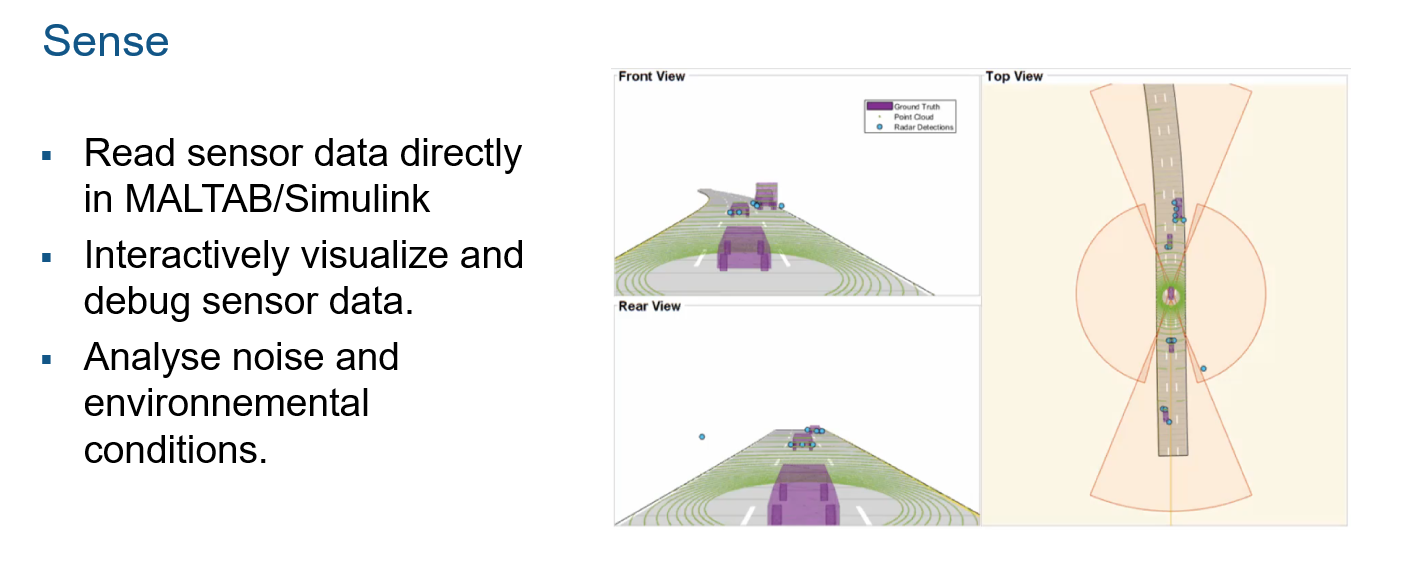

## Connecting MATLAB/Simulink to ROS

`rosinit` starts the global ROS node with a default MATLAB® name and tries to connect to a ROS master running on `localhost` and port `11311`. If the global ROS node cannot connect to the ROS master, `rosinit` also starts a ROS core in MATLAB, which consists of a ROS master, a ROS parameter server, and a rosout logging node.

rosshutdown

Shutting down global node /matlab_global_node_66439 with NodeURI http://192.168.137.1:57110/


%rosinit 192.168.137.134
rosinit 192.168.1.127

Initializing global node /matlab_global_node_15972 with NodeURI http://192.168.1.132:57403/


## Initialize Subscriber

Use `rossubscriber` to create a ROS subscriber for receiving messages on the ROS network. To send messages, use `rospublisher`. To wait for a new ROS message, use the [`receive`](https://www.mathworks.com/help/ros/ref/receive.html) function with your created subscriber.

laserSub = rossubscriber('/scan');
laserdata = receive(laserSub,1)

laserdata =   ROS LaserScan message with properties:

       MessageType: 'sensor_msgs/LaserScan'
            Header: [1×1 Header]
          AngleMin: -2.3562
          AngleMax: 2.3562
    AngleIncrement: 0.0044
     TimeIncrement: 1.7361e-05
          ScanTime: 0.0250
          RangeMin: 0.0200
          RangeMax: 30
            Ranges: [1081×1 single]
       Intensities: [1081×1 single]

  Use showdetails to show the contents of the message


## Interactively visualize data

`plot(`[`scanMsg`](https://www.mathworks.com/help/ros/ref/plot.html#buqbjtl-scan)`)` plots the laser scan readings specified in the input [`LaserScan`](https://www.mathworks.com/help/ros/ref/laserscan.html) object message. Axes are automatically scaled to the maximum range that the laser scanner supports. When plotting ROS laser scan messages, MATLAB® follows the standard ROS convention for axis orientation. This convention states that **positive *****x***** is forward, positive *****y *****is left, and positive *****z***** is up**.

fgh = figure(); % create a figure
% axh = axes('Parent',fgh); % create axes
lnh = plot(laserdata); % plot in those axes

rate = rateControl(10);

while rate.TotalElapsedTime < 20
laserdata = receive(laserSub,1);
axh = axes('Parent',fgh);
lnh = plot(laserdata);
end

## Initialize Publisher

[velPub, velMsg] = rospublisher('/ackermann_cmd_mux/input/navigation');

velMsg.Drive.Speed = 0;
velMsg.Drive.Acceleration = 0.01;
velMsg.Drive.Jerk = 0.01;
velMsg.Drive.SteeringAngle = 0;
velMsg.Drive.SteeringAngleVelocity = 0.03;


## Initialize VFH controller

vfh = controllerVFH;
vfh.UseLidarScan = true;
vfh.DistanceLimits = [0.1 0.6];
vfh.RobotRadius = 0.1;
vfh.MinTurningRadius = 0.2;
vfh.SafetyDistance = 0.15;

rate = rateControl(10);

while rate.TotalElapsedTime < 300
       
        targetDir = 0;
	
        % Get laser scan data
	laserScan = receive(laserSub);        
	ranges = double(laserScan.Ranges);
	angles = double(laserScan.readScanAngles);
                 
	% Create a lidarScan object from the ranges and angles
        scan = lidarScan(ranges,angles);
        
	% Call VFH object to computer steering direction
	steerDir = vfh(scan, targetDir)
    
	% Calculate velocities
	if ~isnan(steerDir) % If steering direction is valid
                desiredV = 0.5;
                w = exampleHelperComputeAngularVelocity(steerDir, 1);
	else % Stop and search for valid direction
		desiredV = -0.1;
		w = 0;
                pause(1);
	end

	% Assign and send velocity commands
	velMsg.Drive.Speed = desiredV;
	velMsg.Drive.SteeringAngle = w;
	send(velPub,velMsg);
        %show(vfh)
        
end

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = -0.6967

steerDir = -0.6967

steerDir = -0.6967

steerDir = -0.6967

steerDir = -0.6967

steerDir = -0.6967

steerDir = -0.6967

steerDir = -0.6967

steerDir = -0.6967

steerDir = -1.1854

steerDir = -1.1854

steerDir = -1.1854

steerDir = -1.1854

steerDir = -1.1854

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.6043

steerDir = -1.5345

steerDir = -1.5345

steerDir = -0.6109

steerDir = -0.5585

steerDir = -0.5061

steerDir = -0.4363

steerDir = -0.3840

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = NaN

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = -0.4175

steerDir = NaN

steerDir = NaN

steerDir = NaN

steerDir = -0.6458

steerDir = -0.5760

steerDir = -0.4887

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0.7316

steerDir = 0.7316

steerDir = 0.7316

steerDir = 0.7316

steerDir = 0.7316

steerDir = 0.7316

steerDir = 0.7316

steerDir = 0.7316

steerDir = 0.7316

steerDir = 0.7316

steerDir = 0.7316

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1505

steerDir = 1.1156

steerDir = 0.9760

steerDir = 0.9061

steerDir = 0.8363

steerDir = 0.8363

steerDir = 0.8014

steerDir = 0.8014

steerDir = 0.7665

steerDir = 0.6967

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = -0.4175

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0.6967

steerDir = 0.6967

steerDir = 0.6967

steerDir = 0.6967

steerDir = 0.6967

steerDir = 1.1854

steerDir = 1.1854

steerDir = 1.1854

steerDir = 1.1854

steerDir = 1.1854

steerDir = 1.1854

steerDir = 1.1854

steerDir = 1.1854

steerDir = 1.1854

steerDir = 1.1854

steerDir = 1.1854

steerDir = 1.1854

steerDir = 1.1854

steerDir = 1.1854

steerDir = 1.1854

steerDir = 1.1854

steerDir = 1.0458

steerDir = 0.9411

steerDir = 0.9061

steerDir = 0.8712

steerDir = 0.8363

steerDir = 0.8363

steerDir = 0.8014

steerDir = 0.7665

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = NaN

steerDir = NaN

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

steerDir = 0

%Stop  
velMsg.Drive.Speed = 0;
velMsg.Drive.SteeringAngle = 0;
send(velPub,velMsg)